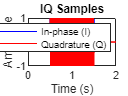

fs = 1000;  % Sampling frequency in Hz
t = 0:1/fs:1-1/fs;  % Time vector
t_plot = 0:1/fs:2-1/fs;  % Time vector
t_plot2 = 0:1/fs:4-2/fs;  % Time vector
f = 50;  % Signal frequency in Hz

I = cos(2*pi*f*t);  % In-phase component
Q = sin(2*pi*f*t);  % Quadrature component

I_padded = [zeros(1, 500), I, zeros(1, 500)];  
Q_padded = [zeros(1, 500), Q, zeros(1, 500)];  

I_noisy = awgn(I_padded, 15);
Q_noisy = awgn(Q_padded, 15);

IQ_signal = I_padded + 1j*Q_padded;  % Combine to form complex IQ signal
IQ_noisy = awgn(IQ_signal, 15);

plot(t_plot, real(IQ_signal), 'b', t_plot, imag(IQ_signal), 'r');
legend('In-phase (I)', 'Quadrature (Q)');
xlabel('Time (s)');
ylabel('Amplitude');
title('IQ Samples');
grid on;

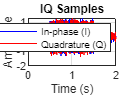


plot(t_plot, real(IQ_noisy), 'b', t_plot, imag(IQ_noisy), 'r');
legend('In-phase (I)', 'Quadrature (Q)');
xlabel('Time (s)');
ylabel('Amplitude');
title('IQ Samples');
grid on;

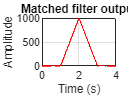


coefs = conj(IQ_signal);
coefs1 = fliplr(coefs);

incidence = conv(IQ_noisy, coefs1);

testmagn = sqrt(real(incidence).^2+imag(incidence).^2);

plot(t_plot2, testmagn, 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title('Matched filter output');
grid on;

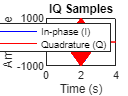


plot(t_plot2, real(incidence), 'b', t_plot2, imag(incidence), 'r');
legend('In-phase (I)', 'Quadrature (Q)');
xlabel('Time (s)');
ylabel('Amplitude');
title('IQ Samples');
grid on;

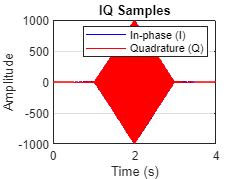

a = conv(I_noisy, I_padded);

b = conv(Q_noisy, Q_padded);

c = conv(I_noisy, Q_padded);

d = conv(Q_noisy, I_padded);

fin_match = (a - b) + 1j*(c+d);

plot(t_plot2, real(fin_match), 'b', t_plot2, imag(fin_match), 'r');
legend('In-phase (I)', 'Quadrature (Q)');
xlabel('Time (s)');
ylabel('Amplitude');
title('IQ Samples');
grid on;

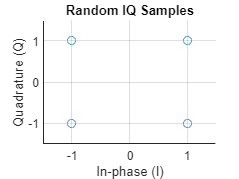

N = 1000;  % Number of samples
I = randi([0, 1], 1, N) * 2 - 1;  % Random in-phase values (-1 or 1)
Q = randi([0, 1], 1, N) * 2 - 1;  % Random quadrature values (-1 or 1)

IQ_signal = I + 1j*Q;  % Combine to form IQ samples

scatter(real(IQ_signal), imag(IQ_signal));
xlabel('In-phase (I)');
ylabel('Quadrature (Q)');
title('Random IQ Samples');
grid on;
axis([-1.5 1.5 -1.5 1.5]);

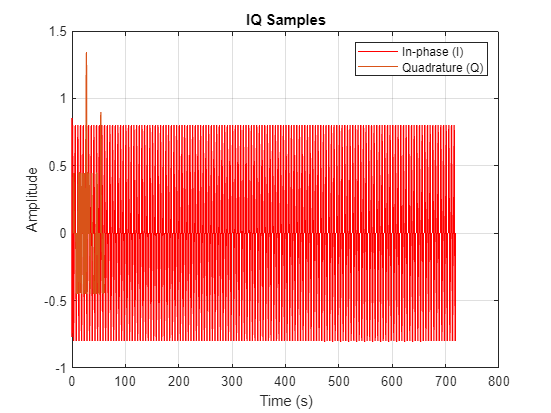

f_signal = 0.2*16e6;        
fs = 16e6;             
t_duration = 500/fs;     

t = 0:1/fs:t_duration-1/fs;
t_series = 0:1/fs:(3*t_duration)-1/fs;

I_h = 0.4*cos(2*pi*f_signal*t);  % In-phase component
Q_h = 0.4*sin(2*pi*f_signal*t);  % Quadrature component

I_hLow = 0.1*cos(2*pi*f_signal*t);  % In-phase component
Q_hLow = 0.1*sin(2*pi*f_signal*t);  % Quadrature component

IQ_signal_h = I_h + 1j*Q_h;  % Combine to form complex IQ signal

IQ_coefs = fliplr(conj(IQ_signal_h(1:64)));

Ih_padded = [zeros(1, 500), I_h, zeros(1, 500)];  
Qh_padded = [zeros(1, 500), Q_h, zeros( 1, 500)];

random_signal = 0.4 * (2*rand(1, 1500) - 1);

IhLow_padded = [zeros(1, 500), I_hLow, zeros(1, 500)];  
QhLow_padded = [zeros(1, 500), Q_hLow, zeros( 1, 500)];

Ih_noise = awgn(Ih_padded, 15);
Qh_noise = awgn(Qh_padded, 15);

IhLow_noise = awgn(IhLow_padded, 15);
QhLow_noise = awgn(QhLow_padded, 15);

input = Ih_noise + 1j*Qh_noise;

plot(t_series, real(input), 'b', t_series, imag(input), 'r');
legend('In-phase (I)', 'Quadrature (Q)');
xlabel('Time (s)');
ylabel('Amplitude');
title('IQ Samples');
grid on;

%Test stimulus generation

Ih2_padded = [I_h, zeros(1, 1000)];  
Qh2_padded = [Q_h, zeros(1, 1000)];

Ih2_noise = awgn(Ih2_padded, 25);
Qh2_noise = awgn(Qh2_padded, 25);

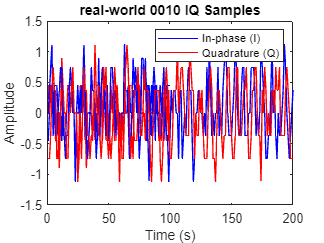

plot(real(samples0010(1:200)), 'b')
hold on; 
plot(imag(samples0010(1:200)), 'r');
legend('In-phase (I)', 'Quadrature (Q)');
xlabel('Time (s)');
ylabel('Amplitude');
title('real-world 0010 IQ Samples');
hold off;

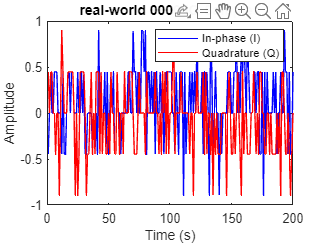

plot(real(samples0000(1:200)), 'b')
hold on; 
plot(imag(samples0000(1:200)), 'r');
legend('In-phase (I)', 'Quadrature (Q)');
xlabel('Time (s)');
ylabel('Amplitude');
title('real-world 0000 IQ Samples');

plot(real(samples0000(1:200)), 'b')
hold on; 
plot(imag(samples0000(1:200)), 'r');
legend('In-phase (I)', 'Quadrature (Q)');
xlabel('Time (s)');
ylabel('Amplitude');
title('real-world 0000 IQ Samples');

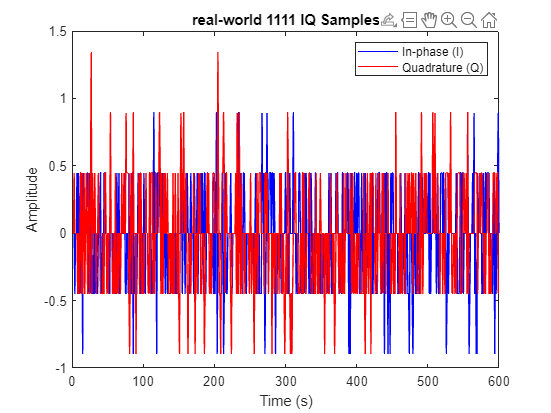

plot(real(samples1111_1(1:600)), 'b')
hold on; 
plot(imag(samples1111_1(1:600)), 'r');
legend('In-phase (I)', 'Quadrature (Q)');
xlabel('Time (s)');
ylabel('Amplitude');
title('real-world 1111 IQ Samples');

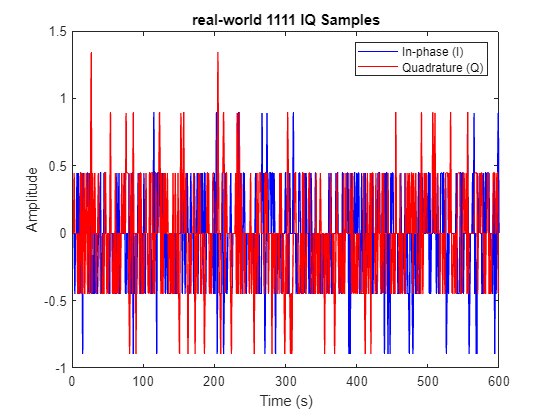

plot(real(samples1111_2(1:200)), 'b')
hold on; 
plot(imag(samples1111_2(1:200)), 'r');
legend('In-phase (I)', 'Quadrature (Q)');
xlabel('Time (s)');
ylabel('Amplitude');
title('real-world 1111 IQ Samples');
hold off;

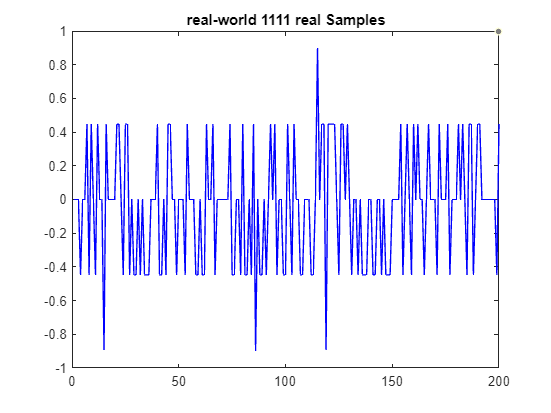

plot(real(samples1111_2(1:200)), 'b')
title('real-world 1111 real Samples');

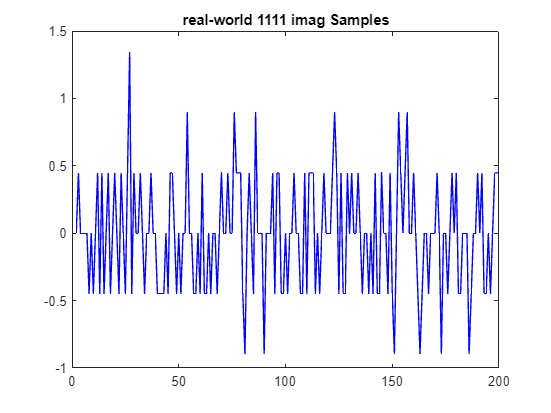

plot(imag(samples1111_2(1:200)), 'r')
title('real-world 1111 imag Samples');

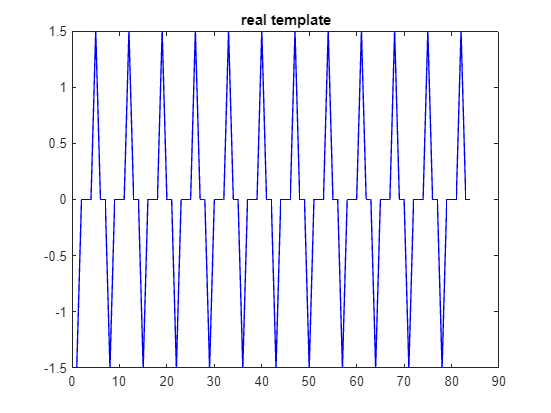

template_short = [0+1.5i, 0+0i, 1.5+0i, 0+0i, 0-1.5i, 0+0i, -1.5+0i];
num_periods = 10; % Number of periods to repeat the sequence
template = repmat(template_short, 1, 12); % Repeat the sequenc
template = fliplr(conj(template));


plot(real(template), 'b')
title('real template');

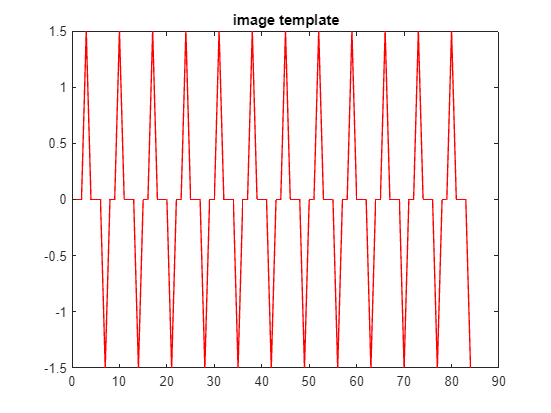


plot(imag(template), 'r')
title('image template');


%template = samples1111_2(1:64);
test = [zeros(1, 500), samples0010(1:500), zeros(1, 500)];